# Quaternion Based Controller

Params

% Simulation Parameters
dt = 0.01; % Time step (s)
T = 10; % Total simulation time (s)
times = 0:dt:T; % Time vector

% Initial Conditions
q = [1; 0; 0; 0]; % Initial quaternion (identity quaternion as 4x1 column vector)
omega = [0; 0; 0]; % Initial angular velocity (rad/s, as a 3x1 column vector)
I = diag([6.5e-4, 6.5e-4, 1.2e-3]); % Inertia matrix (kg·m^2)
torque = [0; 0; 0]; % External torque (Nm)


Reference Trajectory

% Initialize the reference trajectory
traj_1 = zeros(3, length(times));

% Define the step in phi at 2 seconds
for i = 1:length(times)
    if times(i) >= 2
        traj_1(1, i) = 1; % Set phi to 1 radian
    end
    if times(i) >= 4
        traj_1(2, i) = 1; % Set phi to 1 radian
    end
    if times(i) >= 6
        traj_1(3, i) = 1; % Set phi to 1 radian
    end
end
reference_trajectory = traj_1;

% Initialize the reference quaternion array
q_ref = zeros(4, length(times)); % 4xN array for quaternions

% Convert each set of Euler angles to quaternions
for i = 1:length(times)
    % Extract current Euler angles
    phi = reference_trajectory(1, i);
    theta = reference_trajectory(2, i);
    psi = reference_trajectory(3, i);
    
    % Convert Euler angles to quaternion
    q_ref(:, i) = euler_to_quaternion(phi, theta, psi);
end


% Memory for Storing Results
quaternion_history = zeros(4, length(times)); % To store quaternion over time
omega_history = zeros(3, length(times)); % To store angular velocity over time
torque_history = zeros(3, length(times)); % Torque history
q_err_history = zeros(4, length(times)); % Quaternion error history


Simulation

Kq = 0.02;
Kw = 0.005;

% Simulation Loop
count = 1;
tic
for t_idx = 1:length(times)
    % Current reference quaternion
    q_refs = q_ref(:, t_idx);

    % Compute Quaternion Error
    q_err = q_error(q_refs, q); % Error quaternion

    % Compute Torque Using P^2 Controller
    q_err_squared = q_err(2:4); % Square of vector components (q1^2, q2^2, q3^2)
    tau = -Kq * q_err_squared - Kw * omega; % Torque command

    % Angular Velocity Dynamics
    omega_dot = I \ (tau - cross(omega, I * omega));

    % Update Angular Velocity
    omega = omega + dt * omega_dot;

    % Quaternion Kinematics
    omega_quat = [0; omega]; % Angular velocity as a pure quaternion
    q_dot = -0.5 * q_mult(omega_quat, q); % Quaternion derivative

    % Update Quaternion
    q = q + dt * q_dot;
    q = q / norm(q); % Normalize quaternion

    % Store Results
    quaternion_history(:, t_idx) = q;
    omega_history(:, t_idx) = omega;
    torque_history(:, t_idx) = tau; % Store the computed torque
    q_err_history(:, t_idx) = q_err; % Store the computed quaternion error  
end
toc

Elapsed time is 0.087335 seconds.


Plotting

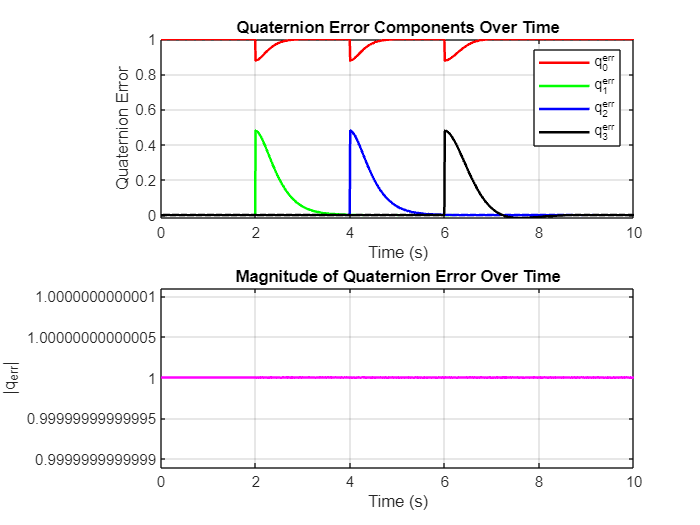

% Plot Results
% Plot Quaternion Error Components
figure;
subplot(2, 1, 1);
plot(times, q_err_history(1, :), 'r', 'LineWidth', 1.5); hold on;
plot(times, q_err_history(2, :), 'g', 'LineWidth', 1.5);
plot(times, q_err_history(3, :), 'b', 'LineWidth', 1.5);
plot(times, q_err_history(4, :), 'k', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Quaternion Error');
title('Quaternion Error Components Over Time');
legend('q_0^{err}', 'q_1^{err}', 'q_2^{err}', 'q_3^{err}');
grid on;

% Plot Magnitude of Quaternion Error (Optional)
subplot(2, 1, 2);
q_err_magnitude = vecnorm(q_err_history); % Magnitude of quaternion error
plot(times, q_err_magnitude, 'm', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('|q_{err}|');
title('Magnitude of Quaternion Error Over Time');
grid on;

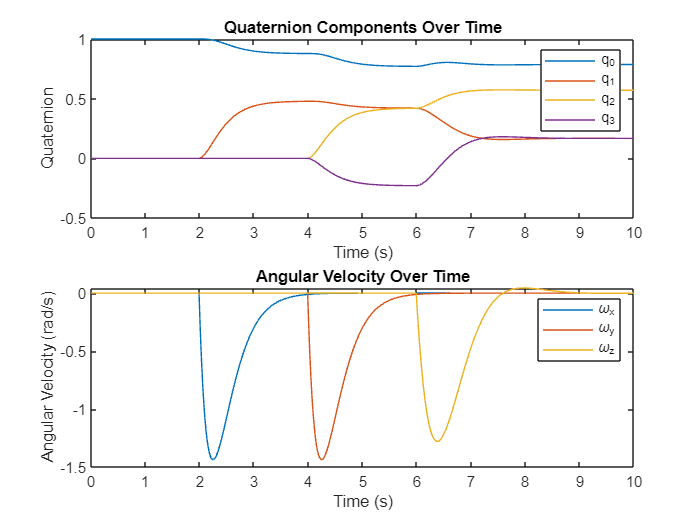


figure;
subplot(2, 1, 1);
plot(times, quaternion_history);
title('Quaternion Components Over Time');
xlabel('Time (s)');
ylabel('Quaternion');
legend('q_0', 'q_1', 'q_2', 'q_3');

subplot(2, 1, 2);
plot(times, omega_history);
title('Angular Velocity Over Time');
xlabel('Time (s)');
ylabel('Angular Velocity (rad/s)');
legend('\omega_x', '\omega_y', '\omega_z');

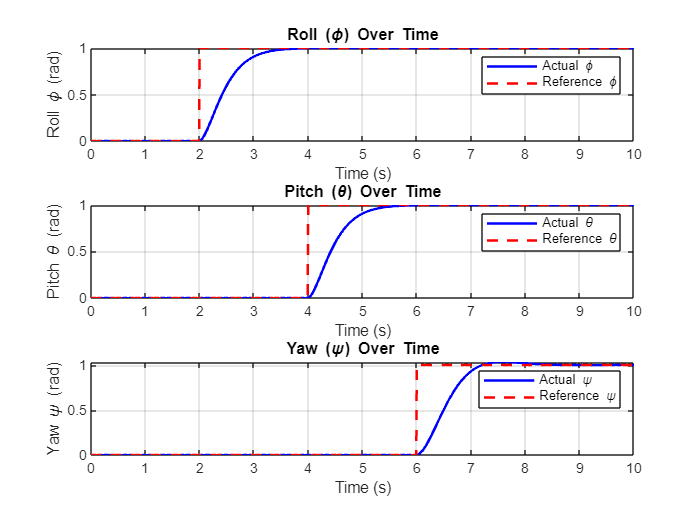

% Initialize arrays for Euler angles
euler_angles = zeros(3, length(times)); % Rows: [phi; theta; psi], Columns: time steps

% Convert quaternion history to Euler angles
for i = 1:length(times)
    q = quaternion_history(:, i); % Extract quaternion at each time step
    [phi, theta, psi] = quaternion_to_euler(q); % Convert to Euler angles
    euler_angles(:, i) = [phi; theta; psi]; % Store angles
end

% Plot Results
figure;

% Subplot 1: Roll (phi)
subplot(3, 1, 1);
plot(times, euler_angles(1, :), 'b', 'LineWidth', 1.5); hold on;
plot(times, reference_trajectory(1, :), 'r--', 'LineWidth', 1.5);
title('Roll (\phi) Over Time');
xlabel('Time (s)');
ylabel('Roll \phi (rad)');
legend('Actual \phi', 'Reference \phi');
grid on;

% Subplot 2: Pitch (theta)
subplot(3, 1, 2);
plot(times, euler_angles(2, :), 'b', 'LineWidth', 1.5); hold on;
plot(times, reference_trajectory(2, :), 'r--', 'LineWidth', 1.5);
title('Pitch (\theta) Over Time');
xlabel('Time (s)');
ylabel('Pitch \theta (rad)');
legend('Actual \theta', 'Reference \theta');
grid on;

% Subplot 3: Yaw (psi)
subplot(3, 1, 3);
plot(times, euler_angles(3, :), 'b', 'LineWidth', 1.5); hold on;
plot(times, reference_trajectory(3, :), 'r--', 'LineWidth', 1.5);
title('Yaw (\psi) Over Time');
xlabel('Time (s)');
ylabel('Yaw \psi (rad)');
legend('Actual \psi', 'Reference \psi');
grid on;

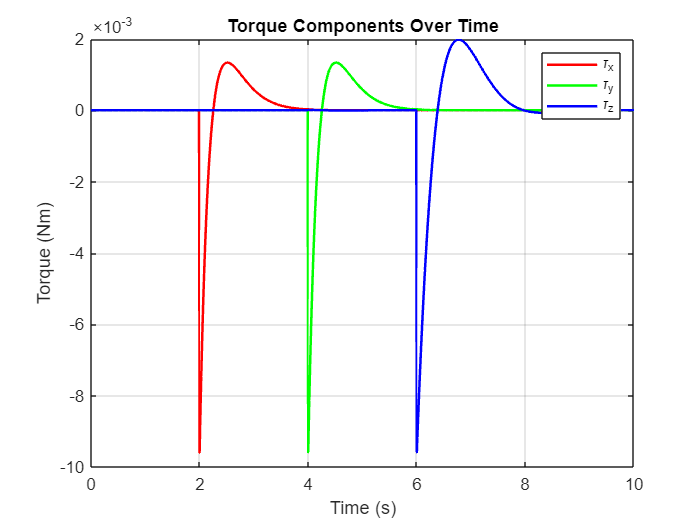

% Plot Torque Components
figure;
plot(times, torque_history(1, :), 'r', 'LineWidth', 1.5); hold on;
plot(times, torque_history(2, :), 'g', 'LineWidth', 1.5);
plot(times, torque_history(3, :), 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Torque (Nm)');
title('Torque Components Over Time');
legend('\tau_x', '\tau_y', '\tau_z');
grid on;

Quaternion Functions

function result = q_mult(p, q)
    % Function to compute the quaternion product p ⊗ q
    % Input:
    %   p: 1x4 quaternion vector [p0, p1, p2, p3]
    %   q: 1x4 quaternion vector [q0, q1, q2, q3]
    % Output:
    %   result: 1x4 quaternion result of p ⊗ q

    % Extract components of p and q
    p0 = p(1); p1 = p(2); p2 = p(3); p3 = p(4);
    q0 = q(1); q1 = q(2); q2 = q(3); q3 = q(4);
    
    % Compute the components of the resulting quaternion
    r0 = p0*q0 - p1*q1 - p2*q2 - p3*q3;
    r1 = p0*q1 + p1*q0 + p2*q3 - p3*q2;
    r2 = p0*q2 - p1*q3 + p2*q0 + p3*q1;
    r3 = p0*q3 + p1*q2 - p2*q1 + p3*q0;

    % Combine results into a 4x1 vector
    result = [r0; r1; r2; r3];
end

function norm_q = q_norm(q)
    % Compute the norm of a quaternion q
    % Input:
    %   q: 1x4 quaternion vector [q0, q1, q2, q3]
    % Output:
    %   norm_q: scalar norm of the quaternion

    norm_q = sqrt(sum(q.^2)); % Compute the Euclidean norm
end

function q_conj = q_conjugate(q)
    % Compute the conjugate of a quaternion q
    % Input:
    %   q: 1x4 quaternion vector [q0, q1, q2, q3]
    % Output:
    %   q_conj: 1x4 quaternion conjugate [q0, -q1, -q2, -q3]

    q_conj = [q(1), -q(2), -q(3), -q(4)];
end

function q_inv = q_inverse(q)
    % Compute the inverse of a quaternion q
    % Input:
    %   q: 1x4 quaternion vector [q0, q1, q2, q3]
    % Output:
    %   q_inv: 1x4 quaternion inverse

    % Compute the conjugate
    q_conj = q_conjugate(q);

    % Compute the norm squared
    norm_q_squared = sum(q.^2);

    % Compute the inverse
    q_inv = q_conj / norm_q_squared;
end

function w = frame_transform(q, v)
    % Perform frame transformation using a quaternion
    % Inputs:
    %   q: 1x4 quaternion vector [q0, q1, q2, q3]
    %   v: 1x3 vector [vx, vy, vz] (the 3D vector to transform)
    % Output:
    %   w: 1x3 transformed vector

    % Step 1: Convert the 3D vector into a pure quaternion
    v_quat = [0, v];

    % Step 2: Compute the quaternion conjugate
    q_conj = q_conjugate(q);

    % Step 3: Perform the transformation
    % w_quat = q ⊗ v_quat ⊗ q^*
    w_quat = q_mult(q_mult(q, v_quat), q_conj);

    % Step 4: Extract the vector part of the resulting quaternion
    w = w_quat(2:4);
end

function q = euler_to_quaternion(phi, theta, psi)
    % Convert Euler angles (phi, theta, psi) to a quaternion
    % Inputs:
    %   phi: Roll angle (in radians)
    %   theta: Pitch angle (in radians)
    %   psi: Yaw angle (in radians)
    % Output:
    %   q: 1x4 quaternion [q0, q1, q2, q3] (w, x, y, z)

    % Precompute half angles
    half_phi = phi / 2;
    half_theta = theta / 2;
    half_psi = psi / 2;

    % Compute trigonometric terms
    c_phi = cos(half_phi); s_phi = sin(half_phi);
    c_theta = cos(half_theta); s_theta = sin(half_theta);
    c_psi = cos(half_psi); s_psi = sin(half_psi);

    % Compute quaternion components
    q0 = c_phi * c_theta * c_psi + s_phi * s_theta * s_psi;
    q1 = s_phi * c_theta * c_psi - c_phi * s_theta * s_psi;
    q2 = c_phi * s_theta * c_psi + s_phi * c_theta * s_psi;
    q3 = c_phi * c_theta * s_psi - s_phi * s_theta * c_psi;

    % Return quaternion
    q = [q0, q1, q2, q3];
end

function [phi, theta, psi] = quaternion_to_euler(q)
    % Convert a quaternion to Euler angles (phi, theta, psi)
    % Input:
    %   q: 1x4 quaternion [q0, q1, q2, q3] (w, x, y, z)
    % Outputs:
    %   phi: Roll angle (in radians)
    %   theta: Pitch angle (in radians)
    %   psi: Yaw angle (in radians)

    % Extract quaternion components
    q0 = q(1);
    q1 = q(2);
    q2 = q(3);
    q3 = q(4);

    % Compute Euler angles
    phi = atan2(2 * (q0 * q1 + q2 * q3), 1 - 2 * (q1^2 + q2^2));
    theta = asin(2 * (q0 * q2 - q3 * q1));
    psi = atan2(2 * (q0 * q3 + q1 * q2), 1 - 2 * (q2^2 + q3^2));
end

function q_err = q_error(q_ref, q_m)
    % Compute quaternion error: q_err = q_ref ⊗ q_m^*
    % Inputs:
    %   q_ref: 4x1 reference quaternion [q0, q1, q2, q3] (as column vector)
    %   q_m: 4x1 measured quaternion [q0, q1, q2, q3] (as column vector)
    % Output:
    %   q_err: 4x1 quaternion error [q0, q1, q2, q3] (as column vector)

    % Step 1: Compute the conjugate of q_m
    q_m_conj = q_conjugate(q_m); % Conjugate of q_m

    % Step 2: Compute the quaternion product q_ref ⊗ q_m^*
    q_err = q_mult(q_ref, q_m_conj);
end

function tau = attitude_controller(q_err, omega, P_q, P_omega)
    % Compute the torque control command for a quadrotor
    % Inputs:
    %   q_err: 4x1 quaternion error [q0_err, q1_err, q2_err, q3_err] (column vector)
    %   omega: 3x1 angular velocity [omega_x, omega_y, omega_z] (rad/s, column vector)
    %   P_q: 3x3 proportional gain matrix for quaternion error
    %   P_omega: 3x3 proportional gain matrix for angular velocity
    % Output:
    %   tau: 3x1 torque control command (Nm)

    % Extract the vector part of the quaternion error (q1_err, q2_err, q3_err)
    q_err_vec = q_err(2:4);

    % Compute the torque command
    tau = -P_q * q_err_vec - P_omega * omega;
end
